# Actividad 2: Modelado de Energía Cinética

## Objetivo

Para esta actividad se debe obtener el modelo de la energía cinética total para tres configuraciones de robots manipuladores, en este caso el robot péndulo:

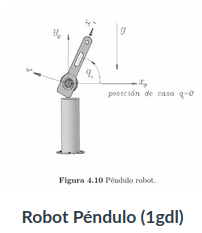

Imagen 1. Modelo

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

tic

syms th1(t)  t  %Angulos de cada articulación
syms m1 Ixx1 Iyy1 Izz1 %Masas y matrices de Inercia
syms t1 %Tiempos
syms l1 lc1 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g


Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición).

RP=[0];

Q= [th1];
disp('Coordenadas articulares');

Coordenadas articulares


pretty (Q);

th1(t)



Sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t); %Utilizo diff para derivadas cuya variable de referencia no depende de otra: ejemplo el tiempo
disp('Velocidades articulares');

Velocidades articulares


pretty (Qp);

 d
-- th1(t)
dt



%Número de grado de libertad del robot
GDL= size(RP,2); %***Siempre se coloca 2, ya que indica la dimensión de las columnas
GDL_str= num2str(GDL);%Convertimos el valor numérico a una cadena de carácteres tipo string


Se declaran las matrices de posición y las de rotación.

%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1);
           l1*sin(th1);
                     0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0; %*** Análisis de robot péndulo
           sin(th1)  cos(th1)  0;
           0         0         1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%****

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%*****

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); %*****

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);


Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
    %Locales
    %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);  %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));
%Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
%matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente th1, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
%Derivadas parciales de y respecto a th1 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11;
              Jv21;
              Jv31]);
pretty(jv_d);

/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /




%Calculamos el jacobiano lineal de forma analítica
%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);


Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

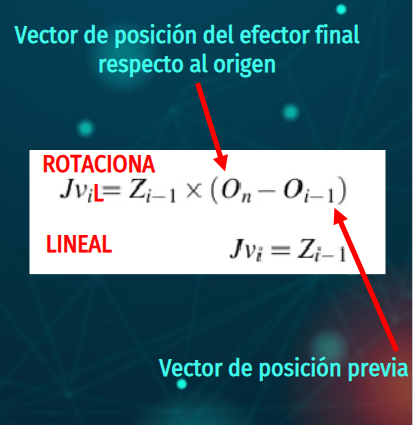

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

for k= 1:GDL
    if ((RP(k)==0)|(RP(k)==1))%Casos: articulación rotacional y prismática

       %Para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));%*****
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las articulaciones prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0 \
|   |
| 0 |
|   |
\ 1 /



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/     _________             \
|      d                    |
| -l1 -- th1(t) sin(th1(t)) |
|     dt                    |
|                           |
|     _________             |
|      d                    |
|  l1 -- th1(t) cos(th1(t)) |
|     dt                    |
|                           |
\             0             /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



### **Energía cinética**

Se declara la distancia del origen del eslabón a su centro de masa con vectores de posición respecto al centro de masa.

posteriormente se crea la matriz de inercia por cada eslabón.

P01=subs(P(:,:,1)/2, l1, lc1);

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

**Función de energía cinética**

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);


**Calculamos la energía cinemática para cada eslabón**

Como este robot péndulo es de un grado de libertad, ya se obtuvo la velocidad lineal (V) y la velocidad angular (W) previamente, por lo que se utilizan esas matrices en la sustitución de la ecuación producto cruz y con la que se obtiene la energía cinética.

V_Total= V+cross(W,P01);
K1= (1/2*m1*(V_Total))'*(1/2*m1*(V_Total)) + (1/2*W)'*(I1*W);

Para finalmente desplegar la energía cinética total de este robot.

disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

      |  d        | 2    |  d        | 2     ______               2          2             2
Izz1  | -- th1(t) |      | -- th1(t) |   cos(th1(t) - th1(t)) |m1|  (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
      | dt        |      | dt        |
--------------------- + ----------------------------------------------------------------------------------
          2                                                  16 l1 lc1



%se recopila el tiempo que tomó ejecutar las operaciones
toc

Elapsed time is 2.250902 seconds.
